# **DBT** Projektwoche WS20/21

`Defekt-Cluster-Korrektur nach dem Verfahren von Efros & Leung (1997)`

`------------------------------`

clear
addpath(genpath(pwd()));

## Einlesen der Textur

Die Textur kann automatisch oder manuell gewählt werden:

pat_selection = "auto";

//TODO um Inpainting erweitern: beliebige Bilder mit zugehörigen Masken

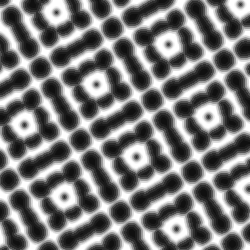

PAT/pat23.tif


switch pat_selection
    case 'auto'
        pattern_list = dir('PAT/pat*.*');
        fpath=fullfile('PAT', pattern_list(randi(numel(pattern_list))).name);
    case 'eigen'
        default_pat='PAT/pat01.tif';
        [file, path] = uigetfile({'PAT/*.*'}, 'Select a pattern', default_pat);
        if file ~= 0
            fpath = [path file];
        else
            fpath = default_pat;
        end
end

[I, ~] = patRead(fpath); imdisplay(I, 'Original image'); disp(fpath);

[Iheight, Iwidth] = size(I);

 


## Parametereinstellung

windowSize = 9; win_half = floor(windowSize/2);
searchArea = 31; s_half= floor(searchArea/2);
scale = "log";
 

[I, ~] = patRead(fpath);
switch scale
    case 'linear'
        % bereits linear
    case 'log'
        I = log(I+1);
        invI = @(x) exp(x)-1;
    case 'gamma'
        gamma=2.2;
        I = imadjust(I,[],[],(1/gamma));
end

## Defekte Cluster zufügen

Man beachte, dass in der Maske **die Defektcluster **mit 1 gekennzeichnet sind, und die gültigen Pixel mit 0 (im Gegensatz zu den gängigen Verfahren). 

//TODO Möglichkeit,´ánschließend Zufallsrauschen zu addieren

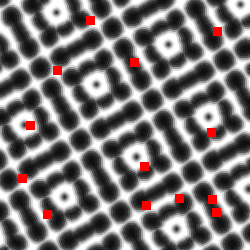

 

clusterSize =9;
numDefects = 13;

mask = pxDecay(I, 'ClusterSize', clusterSize, 'ROISize', windowSize, 'NumDefects', numDefects);
imdisplay(imoverlay(invI(I), mask, 'red'));

mask_copy = mask;

## Summum opus

Eine wiederholte Nutzung ist möglich -- ab hier kann man die Synthhese durch mehrere Iterationen mit "Run to End" derselben Maske und des Bildes überprüfen

I_new = I.*(~mask_copy);
mask = mask_copy;

Solange die Maske Defektpixel hat, werden diese regionenweise untersucht. Man fange am Clusterrand an, d.h. an den Stellen mit den meisten bekannten Nachbarn, und lese die Grenzpixel der Regionen in der Binärmaske aus.

while any(any(mask))
    %bb = bwboundaries(mask);
    
    [r,c] = find(bwperim(mask) == 1);
    region = [r c];
    
    if numel(region(:,1)) > 1
        region = region(randperm(length(region)),:);
    end
         
    for k=1:size(region,1)
        pix = region(k,:);
        
        [roi, mask_roi, roiBig, mask_roiBig] = blocParty(pix, I_new, mask, win_half, s_half);
        
        if numel(mask_roi(mask_roi == 0)) > 0
            [prediction, err] = ssd(roi, roiBig, mask_roi, mask_roiBig);
            
            if ~err
                I_new(pix(1), pix(2)) = prediction;
                mask(pix(1), pix(2)) = 0;
            end
        end
    end
end

### Ende

Rückwandlung in den intensitätsslinearen Skalenraum und Gegenüberstellung des defekten Bildes mit dem synthetisierten:

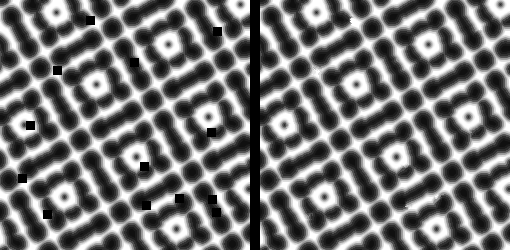

if scale == "log"
    I = invI(I);
    I_new = invI(I_new);
elseif scale == "gamma"
    I = imadjust(I,[],[],(gamma));
    I_new = imadjust(I_new,[],[],(gamma));
end
scale = "linear";

imdisplay([I.*(~mask_copy), zeros(size(I_new,1),10), I_new]);

## Ähnlichkeitsmetriken

#### **Mean Absolute Error (MAE)**

disp(meanabsolute(I_new, I))

    0.0010162


#### **Mean Squared Error (MSE)**

disp(meansquared(I_new, I))

   0.00017042


Weitere Bildbeurteilungsmetriken, die sich mehr auf strukturelle Eigenschaften konzentrieren als auf reine Helligkeitsunterschiede:

[ *Zur Zeit nicht aussagekräftig genug, da die Clusterfläche verhältnisweise klein ist, wären in Theorie aber bei der Arbeit mit größeren Falschregionen und Image Quilting unerlässlich. Ansonsten bietet sich entweder eine separate Betrachtung der Ausschnitte mit den Defektclusters (z.B. über Angaben von *`regionprops()`*) *]

#### Structural Similarity Index Measure (SSIM) 

[ssimval, ssimmap] = ssim(I_new, I);
disp(ssimval)

      0.99692


#### Correlation Coefficient nach Pearson

disp(corr2(I, I_new))

      0.99916
